% execute math script
out = evalc('hobbing');
clearvars out ans traj

## Bedatung der Variablen für die Simulation

while true

### Werkstück offset

a = 0;
b = 0;
c = 0;
% point of interest
poi = [60 0 -11.4937];      % [mm] punkt in werkzeugkoordinaten

### Vorschübe

#### x-Achse

fX_WZrad = 0;
x = 0;          % offset

#### z-Achse

fZ_WZrad = 0;
z = 0;          % offset

#### y-Achse

fY_WZrad = 0;
y = 0;
Y_shift = 0;

#### C-Achse

zWst = 50;              % zähnezahl werkstuck
zWz = 1;                % zähnezahl werkzeug
f_WSTrad = zWz / zWst;
ga = 0;                 % werkstuckwinkel offset

#### A-Achse

A = 0;          % winkel A in rad

### run Simulation

nB = 1;         % 1*s^-1, drehzahl der b-achse

% simulation setup
tSim = 32*pi;
if exist('traj',"var")
    simOut = sim('ASM00021');
%     clearvars traj
    return
end

## Bedatung der Variablen für analytische Berechnung

#### Werkstück offset

es ändert sich nichts

#### x-achse

x = 300;    % [mm] abstand in CSYS zu WZ-CS

#### z-Achse

z = 75;     % [mm] abstand in CSYS zu WZ-CS

#### y-Achse, C-Achse, A-Achse

es ändert sich nichts

### ausführen der analytischen Berechnung

nSchritt = 1e2;
% drehgechwindigkeit
slopeB = nB;

anaT = linspace(0,tSim,nSchritt+1)';
currB = 0;
traj = nan(length(anaT),3);
logB = nan(length(anaT),1);

iterT = tic;
% 1:nSchritt+1
for schritt = 1:length(anaT)
    currB = slopeB * anaT(schritt);
    B = currB;
    logB(schritt) = B;
    TMgesamt = double(vpa(subs(Gesamt)));
    traj(schritt,:) = applytm(poi',TMgesamt)';
    %     traj(schritt,:) = app
end
fprintf('[ %s ] time to run the iteration: %.3f sec.\n',datestr(now,'HH:mm:ss'),toc(iterT))

[ 18:10:59 ] time to run the iteration: 5.169 sec.


## Plotting

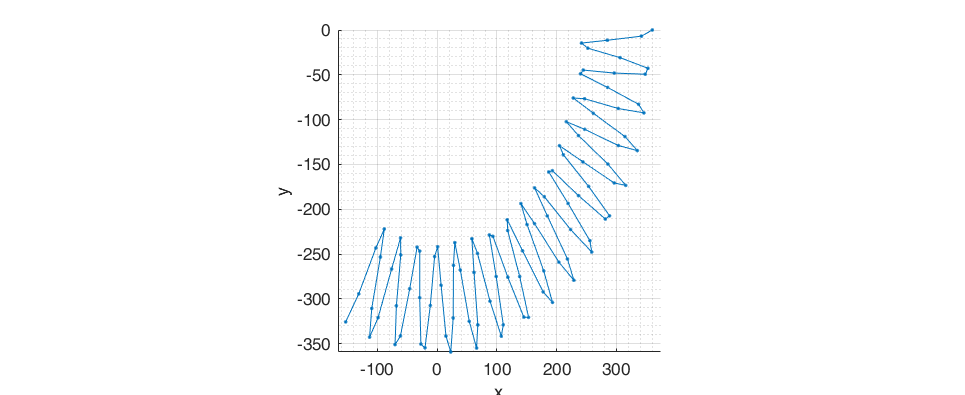

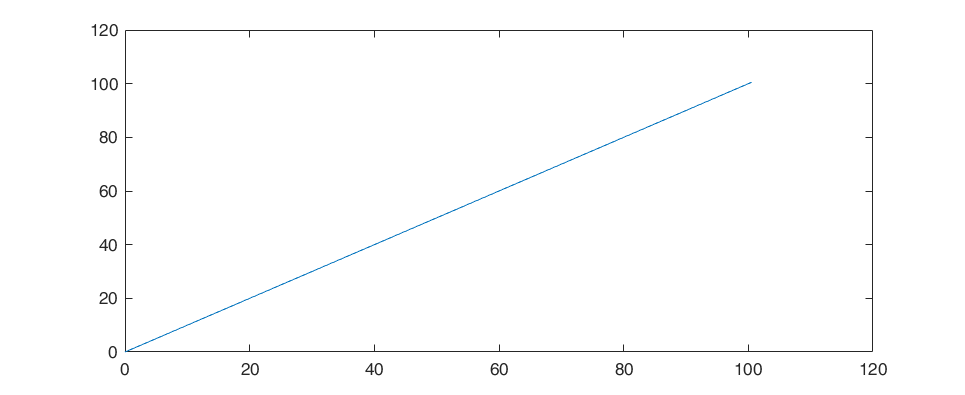

[figH,axH] = getFigH(2,'Color','white'); set(0,'CurrentFigure',figH(1));

Trajectorie

line(traj(:,1),traj(:,2),traj(:,3),'Marker','.','LineStyle','-')
xlabel('x');ylabel('y');zlabel('z')
grid on;
grid minor;
axis vis3d;

Log

set(0,'CurrentFigure',figH(2));
plot(anaT,logB)
end